# Sessió 5:

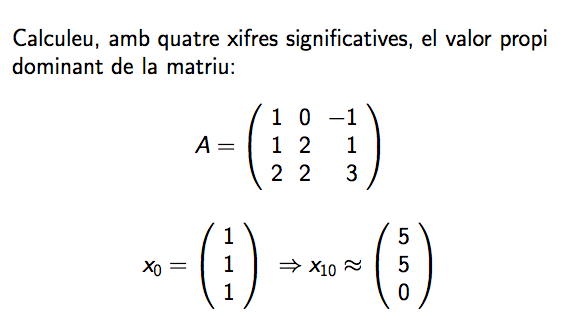

A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


x = [1 1 1]'

x =      1
     1
     1



k = 0;
control = 1;
while (control > eps) && (k < 10)
    y = x;
    z = A * x;
    m = norm(z,'inf')
    x = z/norm(z,'inf')
    k = k+1;
    control = norm(x-y,'inf');
end

m = 7

x =          0
    0.5714
    1.0000


m = 4.1429

x =    -0.2414
    0.5172
    1.0000


m = 3.5517

x =    -0.3495
    0.5049
    1.0000


m = 3.3107

x =    -0.4076
    0.5015
    1.0000


m = 3.1877

x =    -0.4416
    0.5005
    1.0000


m = 3.1178

x =    -0.4624
    0.5001
    1.0000


m = 3.0755

x =    -0.4755
    0.5000
    1.0000


m = 3.0491

x =    -0.4839
    0.5000
    1.0000


m = 3.0322

x =    -0.4894
    0.5000
    1.0000


m = 3.0213

x =    -0.4930
    0.5000
    1.0000



vep = x

vep =    -0.4930
    0.5000
    1.0000


vap = m

vap = 3.0213

iteracions = k -1

iteracions = 9

residu = norm(A*vep-vap*vep)

residu = 0.0088

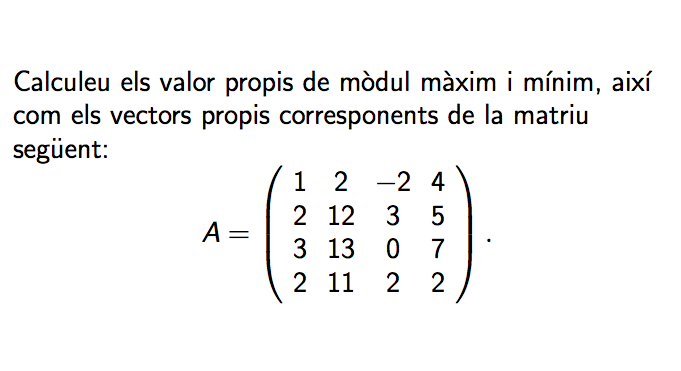

clear variables;
A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
x = [1, 0, 0, 1]';
tol = eps; kmax = 50;
[vap, vep, iteracions, residu] = potencia(A,x,kmax,tol)

residu = 5.3114e-16

vap = 0.0122

vep =     1.0000
   -0.2257
    0.2501
   -0.0090


iteracions = 7

residu = 5.3114e-16

[vap, vep, iteracions, residu] = potencia_inversa(A,x,kmax,tol)

residu = 5.3114e-16

vap = 0.0122

vep =     1.0000
   -0.2257
    0.2501
   -0.0090


iteracions = 7

residu = 5.3114e-16

A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


i = 1;
while (i <= 10)
    [Q,R] = qr(A);
    A = R * Q
    i = i + 1;
end

A =     4.0000   -0.0000    1.4142
    1.7321    1.0000    0.0000
   -1.4142    0.0000    1.0000


A =     3.8571   -1.1664   -2.4004
    0.4666    0.8095    0.3563
    0.4364   -0.1782    1.3333


A =     3.4860   -1.3727    2.6723
    0.1734    0.9043   -0.5835
   -0.1812    0.1000    1.6098


A =     3.2877   -1.4132   -2.7739
    0.0824    0.9491    0.6867
    0.0916   -0.0566    1.7632


A =     3.1776   -1.4210    2.8215
    0.0448    0.9708   -0.7392
   -0.0516    0.0336    1.8516


A =     3.1126   -1.4211   -2.8469
    0.0263    0.9823    0.7686
    0.0309   -0.0208    1.9050


A =     3.0727   -1.4197    2.8617
    0.0161    0.9890   -0.7860
   -0.0193    0.0132    1.9383


A =     3.0474   -1.4182   -2.8706
    0.0102    0.9929    0.7968
    0.0123   -0.0085    1.9596


A =     3.0312   -1.4170    2.8763
    0.0066    0.9954   -0.8036
   -0.0080    0.0055    1.9734


A =     3.0206   -1.4161   -2.8799
    0.0043    0.9970    0.8080
    0.0052   -0.0036    1.9824


clear variables;
A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


k = 0;
n = 1;
while (k < 150 && n > eps)
    [Q,R] = qr(A);
    A = R*Q;
    norm(tril(A,-1),'inf')
    k = k+1;
end

ans = 1.7321

ans = 0.6146

ans = 0.2812

ans = 0.1481

ans = 0.0852

ans = 0.0517

ans = 0.0324

ans = 0.0208

ans = 0.0135

ans = 0.0088

ans = 0.0058

ans = 0.0039

ans = 0.0026

ans = 0.0017

ans = 0.0011

ans = 7.5250e-04

ans = 5.0117e-04

ans = 3.3389e-04

ans = 2.2249e-04

ans = 1.4829e-04

ans = 9.8838e-05

ans = 6.5883e-05

ans = 4.3918e-05

ans = 2.9277e-05

ans = 1.9518e-05

ans = 1.3011e-05

ans = 8.6744e-06

ans = 5.7834e-06

ans = 3.8567e-06

ans = 2.5732e-06

ans = 1.7198e-06

ans = 1.1551e-06

ans = 7.8716e-07

ans = 5.5901e-07

ans = 4.4114e-07

ans = 4.3103e-07

ans = 5.6123e-07

ans = 9.2191e-07

ans = 1.7101e-06

ans = 3.3311e-06

ans = 6.6029e-06

ans = 1.3166e-05

ans = 2.6307e-05

ans = 5.2598e-05

ans = 1.0519e-04

ans = 2.1041e-04

ans = 4.2097e-04

ans = 8.4251e-04

ans = 0.0017

ans = 0.0034

ans = 0.0068

ans = 0.0138

ans = 0.0281

ans = 0.0587

ans = 0.1277

ans = 0.2968

ans = 0.7111

ans = 1.0378

ans = 0.5497

ans = 0.2272

ans = 0.1000

ans = 0.0467

ans = 0.0225

ans = 0.0111

ans = 0.0055

ans = 0.0027

ans = 0.0014

ans = 6.8085e-04

ans = 3.4024e-04

ans = 1.7007e-04

ans = 8.5024e-05

ans = 4.2509e-05

ans = 2.1254e-05

ans = 1.0627e-05

ans = 5.3133e-06

ans = 2.6566e-06

ans = 1.3283e-06

ans = 6.6416e-07

ans = 3.3208e-07

ans = 1.6604e-07

ans = 8.3020e-08

ans = 4.1510e-08

ans = 2.0755e-08

ans = 1.0377e-08

ans = 5.1887e-09

ans = 2.5944e-09

ans = 1.2972e-09

ans = 6.4859e-10

ans = 3.2430e-10

ans = 1.6215e-10

ans = 8.1074e-11

ans = 4.0537e-11

ans = 2.0269e-11

ans = 1.0134e-11

ans = 5.0671e-12

ans = 2.5336e-12

ans = 1.2668e-12

ans = 6.3339e-13

ans = 3.1670e-13

ans = 1.5835e-13

ans = 7.9174e-14

ans = 3.9587e-14

ans = 1.9793e-14

ans = 9.8967e-15

ans = 4.9484e-15

ans = 2.4742e-15

ans = 1.2371e-15

ans = 6.1855e-16

ans = 3.0927e-16

ans = 1.5464e-16

ans = 7.7318e-17

ans = 3.8659e-17

ans = 1.9330e-17

ans = 9.6648e-18

ans = 4.8324e-18

ans = 2.4162e-18

ans = 1.2081e-18

ans = 6.0405e-19

ans = 3.0202e-19

ans = 1.5101e-19

ans = 7.5506e-20

ans = 3.7753e-20

ans = 1.8877e-20

ans = 9.4383e-21

ans = 4.7191e-21

ans = 2.3596e-21

ans = 1.1798e-21

ans = 5.8989e-22

ans = 2.9495e-22

ans = 1.4747e-22

ans = 7.3737e-23

ans = 3.6868e-23

ans = 1.8434e-23

ans = 9.2171e-24

ans = 4.6085e-24

ans = 2.3043e-24

ans = 1.1521e-24

ans = 5.7607e-25

ans = 2.8803e-25

ans = 1.4402e-25

ans = 7.2008e-26

ans = 3.6845e-26

ans = 2.4563e-26

ans = 1.6375e-26

ans = 1.0917e-26

ans = 7.2780e-27

ans = 4.8520e-27

ans = 3.2347e-27

ans = 2.1564e-27

ans = 1.4376e-27

iteracions = k

iteracions = 150

A

A =     3.0000    3.1305    0.7303
   -0.0000    2.0000    0.8165
    0.0000   -0.0000    1.0000


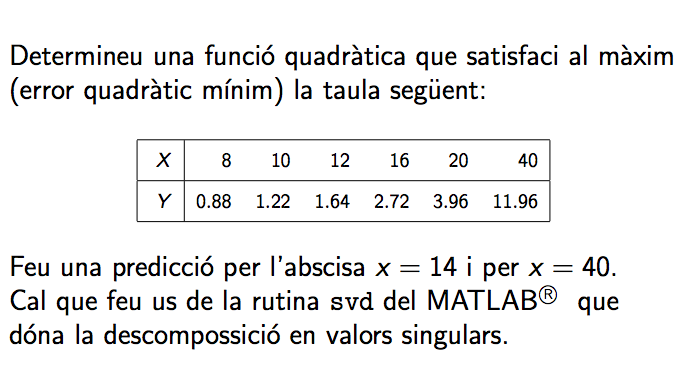

clear vars;
x = [8 10 12 16 20 40]
y = [0.88 1.22 1.64 2.72 3.96 11.96]

function [vap, vep, iteracions, residu] = potencia(A,x,kmax,tol)
k = 0;
control = 1;
while (control > tol) && (k < kmax)
    y = x;
    z = A\x;
    m = norm(z,'inf');
    x = z/norm(z,'inf');
    k = k+1;
    control = norm(x-y,'inf');
end
vep = x;
vap = 1/m;
iteracions = k-1;
residu = norm(A*vep-vap*vep)
end

function [vap, vep, iteracions, residu] = potencia_inversa(A,x,kmax,tol)
k = 0;
control = 1;
while (control > tol) && (k < kmax)
    y = x;
    z = A\x;
    [m,j] = max(abs(z));
    x = z/norm(z,'inf');
    k = k+1;
    control = norm(x-y,'inf');
end
vep = x;
vap = 1/m;
iteracions = k-1;
residu = norm(A*vep-vap*vep)
end